% This live script is used to test the upsampling function
% for the ECE 434 DSP CPX3 project
%
% Author: Ben Cometto
% 20 Nov 24

clear all
close all

% This worked wonderfully before the lpf
% data = [ 1 2 2 1; 
%     3 4 3 2; 
%     5 5 4 5; 
%     6 6 6 6; 
%     6 8 6 9; 
%     7 8 7 9; 
%     9 9 8 11; 
%     11 10 9 13;
%     11 12 11 13;
%     13 14 12 16;
%     13 15 14 17;
%     14 14 15 18;
%     15 13 13 20;]

Fs = 100000;
T = 1/Fs;
N = 2000;
n = 1:2000;
t = n*T;
k = n;
df = Fs/length(k); % Fs/N
f = k*df;

data = [sin(30000*n*T); sin(45000*n*T); 5*n.^0; cos(20000*n*T) + 2*cos(10000*n*T) + 3*sin(25000*n*T)]';

% Prepare data
load lpf_upsample.bin -mat
data_zeros = zeros(2*height(data),width(data))

data_zeros =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


height(data_zeros)

ans =         4000


2*N

ans =         4000


tic
data_u = upsampling(data,num_upsample,data_zeros,2*N);
toc

Elapsed time is 0.005001 seconds.



FsU = 2*Fs;
nU = 1:length(data_u(:,1));
tU = nU/FsU;
kU = nU;
dfU = FsU/length(kU)

dfU =     50


fU = kU*dfU;


% ===== Analysis: Does it work on canned data =====
% Notes: fc at fs/2
%        Scaled by 1/L so multiply by L
%        Can probably speed up with lower order, and can test several other
%        methods of doing the zero padding

col = 1

col =      1


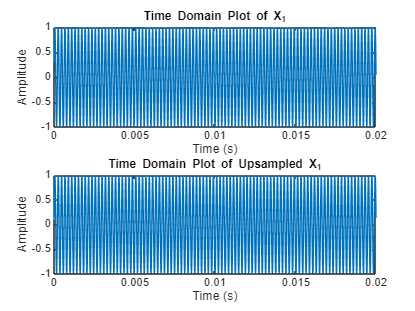


Data = abs(fft(data));
Data_U = abs(fft(data_u));

figure
subplot(2,1,1)
plot(t,data(:,col))
title(sprintf("Time Domain Plot of X_%i",col))
xlabel("Time (s)")
ylabel("Amplitude")

subplot(2,1,2)
plot(tU,data_u(:,col))
title(sprintf("Time Domain Plot of Upsampled X_%i",col))
xlabel("Time (s)")
ylabel("Amplitude")

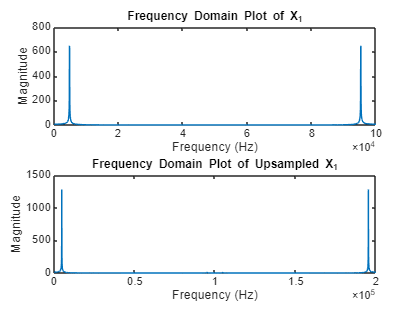



figure
subplot(2,1,1)
plot(f,Data(:,col))
title(sprintf("Frequency Domain Plot of X_%i",col))
xlabel("Frequency (Hz)")
ylabel("Magnitude")
subplot(2,1,2)
plot(fU,Data_U(:,col))
title(sprintf("Frequency Domain Plot of Upsampled X_%i",col))
xlabel("Frequency (Hz)")
ylabel("Magnitude")

% ===== Analysis: Speed =====
% notes: lots of variation... finally at 100k iterations its pretty stable
% at 18us
% in AM of 11/21 slowed down to 27us
% passing in zero vector makes it 25us (all for 200 data points)
% Actually 2000 pts:
% 243 us
% 170 us with 10 order filter
% 60-80 us with 3 order filter!
% 100 us with precomputed indexes

iterations = 1000000

iterations =      1000000


sum = 0;

load lpf_upsample.bin -mat
data_zeros = zeros(2*height(data),width(data));
NU = 2*N;

for k=1:iterations
    time1 = tic;
    upsampling(data,num_upsample,data_zeros,NU);
    time2 = toc(time1);

    sum = sum + time2;
end

averageRuntime = sum/iterations

averageRuntime =      7.263249279999659e-05


% ===== Analysis: Real Data =====
% Notes: the data we care about is under 20KHz,
% so can use a very low order filter for speed

load test_data.mat
data;
data_zeros = zeros(2*height(data),width(data));

tic
data_u = upsampling(data,num_upsample,data_zeros,2*N)

data_u =   -0.040201514430705  -0.026080552372608  -0.003314103340166  -0.045100623716167
  -0.095740367428872  -0.062111134425182  -0.007892575092703  -0.107407652348520
  -0.114760438772432  -0.041361965686754  -0.039448602549062  -0.142421874594617
  -0.085498032354042   0.023333830816488  -0.078465144440248  -0.128487395347765
  -0.046305158070344   0.037887067223302  -0.105410245510290  -0.080216759741005
  -0.021422159415251  -0.006703266366625  -0.103618669607124  -0.027464802592208
  -0.023439439709265  -0.085809472181882  -0.073503556646488   0.000777121523986
  -0.051109334213729  -0.150505268685124  -0.033690758798339  -0.012958293733625
  -0.089581751249564  -0.165346687991083  -0.005592926131718  -0.059932106294234
  -0.115061941872380  -0.121154482379638  -0.006588246077922  -0.111091551529105


toc

Elapsed time is 0.025073 seconds.



FsU = 2*Fs;
nU = 1:length(data_u(:,1));
tU = nU/FsU;
kU = nU;
dfU = FsU/length(kU)

dfU =     50


fU = kU*dfU;

% Plotting
col = 1:4

col =      1     2     3     4


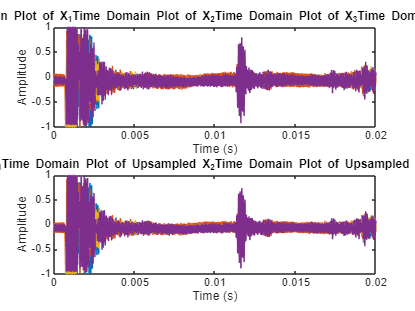


Data = abs(fft(data));
Data_U = abs(fft(data_u));

figure
subplot(2,1,1)
plot(t,data(:,col))
title(sprintf("Time Domain Plot of X_%i",col))
xlabel("Time (s)")
ylabel("Amplitude")

subplot(2,1,2)
plot(tU,data_u(:,col))
title(sprintf("Time Domain Plot of Upsampled X_%i",col))
xlabel("Time (s)")
ylabel("Amplitude")

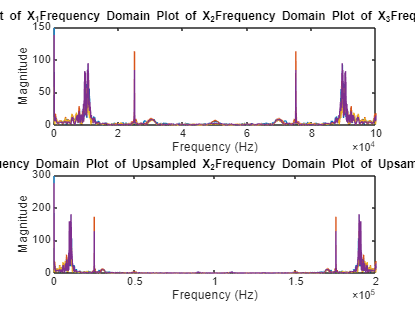



figure
subplot(2,1,1)
plot(f,Data(:,col))
title(sprintf("Frequency Domain Plot of X_%i",col))
xlabel("Frequency (Hz)")
ylabel("Magnitude")
subplot(2,1,2)
plot(fU,Data_U(:,col))
title(sprintf("Frequency Domain Plot of Upsampled X_%i",col))
xlabel("Frequency (Hz)")
ylabel("Magnitude")